close all

fs = 2^13;
T = 0.5;
piano.harmonics = [0.5 0];
piano.envelope = @(t) min(40*t,1).*exp(-4*t);

happy;

v = [];
for i = 1:length(script)
    v = [v tone2(fs,script(i),piano)];
end

mary2;

w = [];
for i = 1:length(script)
    w = [w tone2(fs,script(i),piano)];
end

## A.  initially just adds the two song matrices together. takes the fft one note at a time and coordinates with the music by using a tic/toc system that is at the same speed as the notes are being played.

## B.  eliminates sinusoids above 880Hz simply by setting those indeces to 0, also setting any indeces that contain frequencies as a result of the original Hz.

## Doing the inverse FFT of the result will give back a playable matrix containing only the frequencies you want.

## C.The result is simply played and another tic/toc system is used to display the FFT of the matrix, with axis set to only show frequencies up to 880  

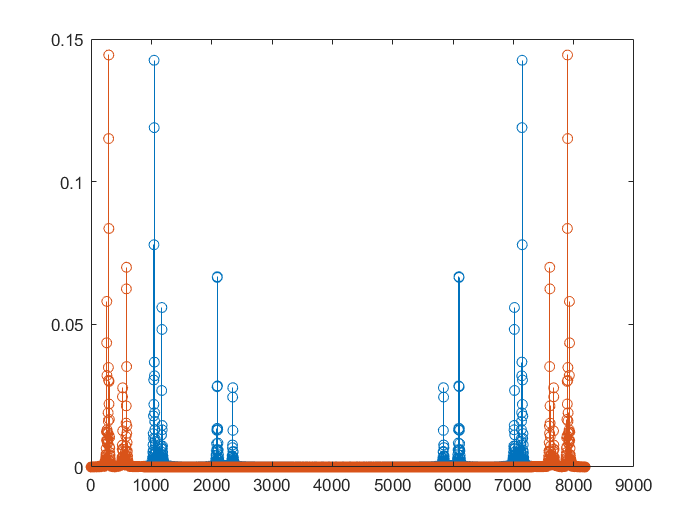

z = v+w;
tic
sound(z,fs)

s = [];
for t = 1:T*fs:length(z)-T*fs
    Z = fft(z(t+(1:T*fs))/(T*fs));

    f = (0:T*fs-1)/T;
    
    while toc<0.5 
    end
    tic
    
    hold off
    stem(f,abs(Z));
    Z((f>880) & (f<fs-880)) = 0;
    hold on
    stem(f,abs(Z));
    pause(0.1)
    
    
    s = [s ifft(Z*(T*fs))];
end


sound(s,fs)
hold off
for t = 1:T*fs:length(s)-T*fs
    S = fft(s(t+(1:T*fs))/(T*fs));

    f = (0:T*fs-1)/T;
    
    while toc<0.5 
    end
    tic
    
    stem(2*f,abs(S));
    axis([0 880 0 0.5])
    pause(0.1)
   
end